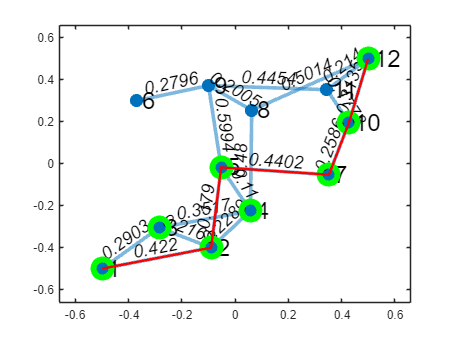

% clear previous variables
clear;
%---- Initial graphs -------
%preset node positions
nodes_positions=[-0.5	-0.5
    -0.09	-0.4
    -0.285	-0.305
    0.0575	-0.225
    -0.0525	-0.0175
    -0.37	0.3
    0.3525	-0.0525
    0.0625	0.255
    -0.1	0.3725
    0.4275	0.195
    0.345	0.3525
    0.5	0.5
    ];

% preset edges and costs
edges=[12	11	0.214
12	10	0.3135
12	8	0.5014
11	10	0.1778
11	9	0.4454
10	7	0.2586
9	8	0.2005
9	6	0.2796
9	5	0.5994
8	4	0.48
5	2	0.179
4	3	0.3517
4	2	0.2289
3	2	0.2169
3	1	0.2903
2	1	0.422
7	5	0.4402
5	4	0.11
];

G=graph(edges(:,1),edges(:,2),edges(:,3)); %the Graph
% suppossing starting node is 1, goal node is 12
star_node =1;
goal_node= 12;
%^^^^^^^^^^^ Initial graphs ^^^^^^^^

%-----------plot the graph------------
% plot the graph
plot(G,"XData",nodes_positions(:,1),"YData",nodes_positions(:,2),"LineWidth",3,"MarkerSize",10,"NodeFontSize",20,"EdgeLabel",G.Edges.Weight,"EdgeFontSize",15)

% mark start and goal nodes
hold on;
plot(nodes_positions(star_node,1),nodes_positions(star_node,2),'bo',"MarkerSize",15,"LineWidth",5);
plot(nodes_positions(goal_node,1),nodes_positions(goal_node,2),'ro',"MarkerSize",15,"LineWidth",5);

hold off;

% a function to plot the nodes
function plotnodes(nodeID,pos)
nodes_positions=pos;
hold on;
plot(nodes_positions(nodeID,1),nodes_positions(nodeID,2),'go',"MarkerSize",15,"LineWidth",5)
hold off;
end
%-^^^^^^^^^^plot the graph^^^^^^^^^^^^

%-------implement priority queue in Matlan--------
function list_queue=add_withPriority(list_queue,priority,element)
    list_queue(end+1,:)=[priority,element]; % adding the element
    [~,idx]=sort(list_queue(:,1)); % sorting queue according to the priority
    list_queue=list_queue(idx,:);  
end
%^^^^^^^^^implement priority queue in Matlan^^^^^^^^^

% ------------------pop element---------------- 
% pop the element with highest priority(loweset priority value)
function [element,list_queue]=pop_min(list_queue)
    % if the list is empty, finish the explore
    if isempty(list_queue)
        disp("finishing the explore");
        return;
    end
    
    % get the element with hightest priority and delete it from the queue
    element=list_queue(1,2); 
    list_queue(1,:)=[];

end
% ^^^^^^^^^^^^^^^^^^^pop element^^^^^^^^^^^^^^^^ 

% -------------calculate the cost----------------
function cost=get_cost(G,node1,node2)
    edgeIndex=findedge(G,node1,node2);
    if edgeIndex>0
        cost=G.Edges.Weight(edgeIndex);
    else
        disp("No edge found");
    end
end
% ^^^^^^^^^^^^^calculate the cost^^^^^^^^^^^^^^^^

% -------------calculate heuristic cost----------------
function cost=heuristic_cost(node_postion,node1,node2)
    x_distance=abs(node_postion(node1,1)-node_postion(node2,1));
    y_distance=abs(node_postion(node1,2)-node_postion(node2,2));
    cost=sqrt(x_distance^2+y_distance^2);
end
% ^^^^^^^^^^^^^calculate heuristic cost^^^^^^^^^^^^^^^^


%------------A* Algorithm-------------
%step 1,2
frontier=[];% define the frontier nodes
frontier=add_withPriority(frontier,0,star_node); % initial the start nodes as the first frontier

came_from=containers.Map('KeyType', 'double', 'ValueType', 'double'); % define reached nodes
came_from(1)=1;

% cost_so_far record the cost from start to current nodes.
cost_so_far=containers.Map('KeyType', 'double', 'ValueType', 'double');
cost_so_far(1)=0;

%step 3
while ~isempty(frontier)

    %step 4
    [current,frontier] = pop_min(frontier); % move the first elements of frontier to current
    

    %plot the current nodes and denoted as green.
    plotnodes(current,nodes_positions); 

    % if we find the goal, then exit the program.
    if current==goal_node
        break;
    end

    %step 5
    %find the neighbors of current nodes
    next_node=neighbors(G,current);

    %step 6
    for i =1:length(next_node)
        new_cost=cost_so_far(current)+get_cost(G,current,next_node(i));
        if ~isKey(cost_so_far,next_node(i)) || new_cost < cost_so_far(next_node(i))
            cost_so_far(next_node(i))=new_cost;
            priority=new_cost+heuristic_cost(nodes_positions,goal_node,next_node(i));
            frontier=add_withPriority(frontier,priority,next_node(i));
            came_from(next_node(i))=current;
        end

        
    end
    pause(0.5); % waiting user's action, to show each explore step
end

% extract path from map
path = [goal_node]; % add the goal node to path

% adding nodes to from goal to (start -1)
previous_node=came_from(goal_node);
while previous_node~=star_node
    path=[path previous_node];
    previous_node=came_from(previous_node);
end
path=[path star_node];% adding  the start node to path

%^^^^^^^^^^^^A* Algorithm^^^^^^^^^^^^^

%-------print the path on graph-----------------
hold on
plot(nodes_positions(path,1),nodes_positions(path,2),'r',"LineWidth",2);
hold off

%^^^^^^^print the path on graph^^^^^^^^^^^^^^^^^
